defaultDir = 'M:\Bergles Lab Data\Papers\P2ry1'; %change if in a different location
cd(defaultDir);
addpath(genpath('MATLAB Functions'));
cd(['Figure 1 - ISCs']);

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\WT_BBE_PT\180816_Cell4_Uncoupled_100microm\18816022_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1201.5 s ~ 20 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 46 MB


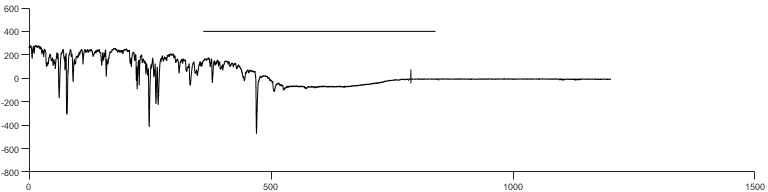

%parameters for analysis
pulse = -100; %test pulse in pA for resistance measurement
pulseTime = [0 0.01 0.2 0.26]; %periods to measure resistance [baseline_start baseline_end ss_start ss_end]
peakProminenceThr = 25; %threshold in pA
conditionTimes = [0 300];
conditions = { 'WT'};

%%dir 
%dname = '.\Data\WT_MRS_PPADS_PT';
%temp = dir(dname);
%folderlist = temp(3:end);
dname = '.\Data\WT_BBE_PT';
temp = dir(dname);
folderlist = [temp(3:end)];


for i = 2:2

    if analyze(3) %change in inward current
        fileList = loadFileList([folderlist(i).folder  '\' folderlist(i).name '\*_gfv.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        %out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        %out = lowpass(d,5,5000);
        figure;
        plot(time, d,'Color','k');
        figQuality(gcf,gca,[8 2]);
        line([360 360+8*60],[400 400],'Color','k');
        xlim([0 1500]);
        ylim([-800 600]);
        export_fig('.\EPS Panels\Examples\BBE.eps')
    end    
end

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\WT_FFA_PT\180817_Cell3\18817017_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1520.9 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 58 MB


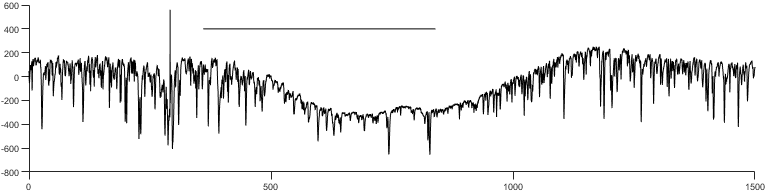

%%ffa

dname = '.\Data\WT_FFA_PT';
temp = dir(dname);
folderlist = [temp(3:end)];
for i = 1:size(folderlist,1)

    if analyze(3) %change in inward current
        fileList = loadFileList([folderlist(i).folder  '\' folderlist(i).name '\*_gfv.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        %out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        %out = lowpass(d,5,5000);
        figure;
        plot(time, d,'Color','k');
        figQuality(gcf,gca,[8 2]);
        line([360 360+8*60],[400 400],'Color','k');
        xlim([0 1500]);
        export_fig('.\EPS Panels\Examples\FFA.eps')
    end    
end

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\WT_TMEM16Ainhibitors\180816_Cell1_T16AInh_A01\18816002_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1800.5 s ~ 30 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 69 MB


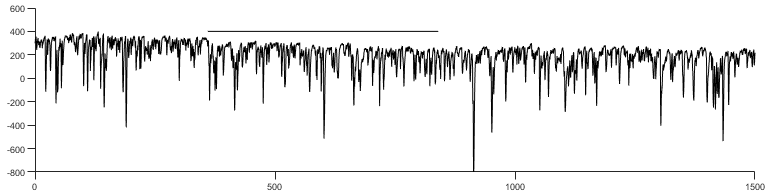

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\WT_TMEM16Ainhibitors\180816_Cell2_T16AInh_A01\18816006_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1219.7 s ~ 20 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 47 MB


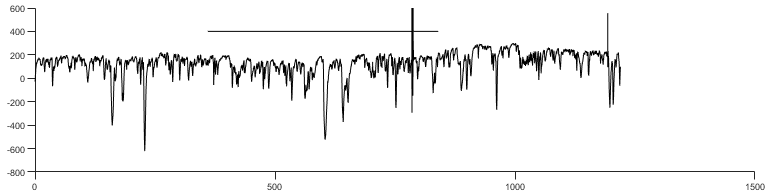

%TMEM16A inh
dname = '.\Data\WT_TMEM16AInh_A01';
temp = dir(dname);
folderlist = [temp(3:end)];


for i = 1:size(folderlist)

    if analyze(3) %change in inward current
        fileList = loadFileList([folderlist(i).folder  '\' folderlist(i).name '\*_gfv.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        %out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        %out = lowpass(d,5,5000);
        figure;
        plot(time, d,'Color','k');
        figQuality(gcf,gca,[8 2]);
        line([360 360+8*60],[400 400],'Color','k');
        xlim([0 1500]);
        ylim([-800 600]);
        export_fig(['.\EPS Panels\Examples\TMEM16Ainh_' num2str(i) '.eps'])
    end    
end

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\WT_Ani9_MRS\180815_Cell3\18815019_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 2106.0 s ~ 35 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 80 MB


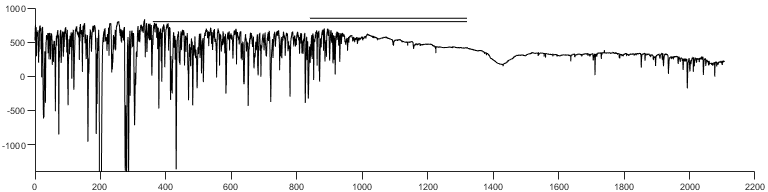

%Ani9 + MRS

dname = '.\Data\WT_Ani9_MRS';
temp = dir(dname);
folderlist = [temp(3:end)];


for i = 3:3

    if analyze(3) %change in inward current
        fileList = loadFileList([folderlist(i).folder  '\' folderlist(i).name '\*_gfv.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        %out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        %out = lowpass(d,5,5000);
        figure;
        plot(time, d,'Color','k');
        figQuality(gcf,gca,[8 2]);
        line([360 360+16*60],[800 800],'Color','k');
        line([360+8*60 360+8*60+8*60],[850 850],'Color','k');
        xlim([0 2200]);
        ylim([-1400 1000]);
        export_fig(['.\EPS Panels\Examples\Ani9_' num2str(i) '.eps'])
    end    
end

for i = 1:size(cellS,2)
    pkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    ampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    intstatBlock(i,:) = [cellS(i).stats.integral]/300;
    rinstatBlock(i,:) = cellS(i).bl_R;
    vmstatBlock(i,:) = cellS(i).Vm;
end

%parameters for analysis
pulse = -100; %test pulse in pA for resistance measurement
pulseTime = [0 0.01 0.2 0.26]; %periods to measure resistance [baseline_start baseline_end ss_start ss_end]
peakProminenceThr = 25; %threshold in pA
conditionTimes = [0 300];

%%dir 
dname = '.\Data\KO_MRS_PPADS_PT';
temp = dir(dname);
folderlist = temp(3:end);
dname = '.\Data\KO_PT';
temp = dir(dname);
folderlist = [folderlist; temp(3:end)];
dname = '.\Data\KO_BBE_PT';
temp = dir(dname);
folderlist = [folderlist; temp(3:end)];

analyze = [1 1 1 0];

if exist('cell') | exist('cellS') 
   clear 'cell' 'cellS'; 
end

for i = 1:size(folderlist,1)
    if analyze(1)
        fileList = loadFileList([folderlist(i).folder '\' folderlist(i).name '\*_p.abf']);
        [d,time] = loadPclampData(fileList{1});
        cellS(i).bl_R = calcRm(d,time,pulse,pulseTime);
    end
    
    if analyze(2)
        fileList = loadFileList([folderlist(i).folder '\' folderlist(i).name '\*_gfi.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, d, 'WindowSize', 60,'StepSize',60);
        cellS(i).Vm = mean(d - out);
        %%figure for assessing basleine
        % figure; plot(time,d);
        %hold on; plot(time,out);
       % plot(time,d-out);
    end
    
    if analyze(3) %change in inward current
        fileList = loadFileList([folderlist(i).folder  '\' folderlist(i).name '\*_gfv.abf']);
        [d,time,SR] = loadPclampData(fileList{1});
        out = msbackadj(time, -d, 'WindowSize', 60,'StepSize',30);
        out = lowpass(out,5,5000);
        %figure for assessing basleine
        % figure; plot(time,out);
%         hold on;
%         plot(time,d-out);
        [pks,locs] = findpeaks(out,time,'MinPeakProminence', peakProminenceThr);
        %uncomment for peaks graph
        %findpeaks(out,time,'MinPeakProminence', peakProminenceThr)
        cellS(i).rawLocPk = [locs pks];
        
        if exist('stats')
            clear 'stats'; 
        end
        for j = 1:size(conditionTimes,1)
            stats(j).condition = conditions{j};
            stats(j).numPeaks = size(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
            stats(j).meanAmp = mean(pks(locs > conditionTimes(j,1) & locs < conditionTimes(j,2)),1);
            cumFunc = cumtrapz(time(time > conditionTimes(j,1) & time < conditionTimes(j,2)), ... 
                                     out(time > conditionTimes(j,1) & time < conditionTimes(j,2)));
            stats(j).integral = cumFunc(end);
            
        end
        
        cellS(i).stats = stats;

    end
   
    if analyze(4)
        fileList = loadFileList([folderlist(i).folder '\' folderlist(i).name '\*_pp.abf']);
        if ~isempty(fileList)
            [d,time] = loadPclampData(fileList{1});
            cellS(i).post_R = calcRm(d,time,pulse,pulseTime);
        end
    end
    
    
end

opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell2\18823008_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell2\18823009_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 320.3 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 12 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell2\18823011_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1528.8 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 58 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell4\18823020_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell4\18823021_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 301.6 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 12 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180823_Cell4\18823025_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1505.5 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 57 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180827_Cell2\18827015_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180827_Cell2\18827016_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 300.7 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 11 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_MRS_PPADS_PT\180827_Cell2\18827018_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 1501.1 s ~ 25 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 57 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180823_Cell1\18823000_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180823_Cell1\18823001_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 180.8 s ~ 3 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 7 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180823_Cell1\18823005_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 301.7 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 12 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180823_Cell3\18823016_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180823_Cell3\18823017_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 187.0 s ~ 3 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 7 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180823_Cell3\18823018_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 301.3 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 11 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180824_Cell1\18824000_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180824_Cell1\18824001_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 255.0 s ~ 4 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 10 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180824_Cell1\18824004_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 304.8 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 12 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180824_Cell3\18824013_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180824_Cell3\18824014_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 300.4 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 11 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180824_Cell3\18824016_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 426.3 s ~ 7 min
sampling interval: 50 µs
memory requirement for complete upload in matlab: 65 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell1\18827000_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell1\18827001_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 301.3 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 11 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell1\18827003_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 392.1 s ~ 7 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 15 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell3\18827020_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell3\18827021_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 330.9 s ~ 6 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 13 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell3\18827022_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 739.1 s ~ 12 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 28 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell4\18827026_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell4\18827027_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 300.9 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 11 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_PT\180827_Cell4\18827029_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 889.1 s ~ 15 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 34 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_BBE_PT\180824_Cell2_Uncoupled\18824009_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_BBE_PT\180824_Cell2_Uncoupled\18824010_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 384.6 s ~ 6 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 15 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_BBE_PT\180824_Cell2_Uncoupled\18824012_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 953.8 s ~ 16 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 36 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_BBE_PT\180824_Cell4_Uncoupled\18824020_p.abf..
**** available channels:
    'IN 0'

data were acquired in waveform fixed-length mode


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_BBE_PT\180824_Cell4_Uncoupled\18824021_gfi.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 325.4 s ~ 5 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 12 MB


opening M:\Bergles Lab Data\Papers\P2ry1\Figure 1 - ISCs\Data\KO_BBE_PT\180824_Cell4_Uncoupled\18824023_gfv.abf..
**** available channels:
    'IN 0'

data were acquired in gap-free mode
total length of recording: 900.6 s ~ 15 min
sampling interval: 200 µs
memory requirement for complete upload in matlab: 34 MB




for i = 1:size(cellS,2)
    KOpkstatBlock(i,:) = [cellS(i).stats.numPeaks]/5;
    KOampstatBlock(i,:) = [cellS(i).stats.meanAmp];
    KOintstatBlock(i,:) = [cellS(i).stats.integral]/300;
    KOrinstatBlock(i,:) = cellS(i).bl_R;
    KOvmstatBlock(i,:) = cellS(i).Vm;
end

compare2C(pkstatBlock,KOpkstatBlock,conditions,'Events Per Minute',[3 2]);

     1



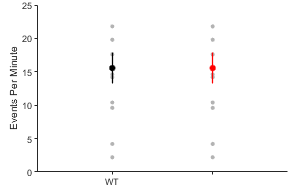

ylim([0 25]);
yticks(0:5:25);


compare2C(ampstatBlock,KOampstatBlock,conditions,'Mean Amp (pA)',[3 2]);

     1



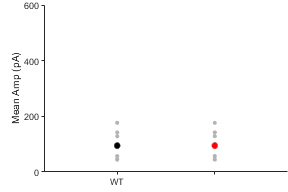

ylim([0 600]);
yticks(0:200:600);


compare2C(intstatBlock,KOintstatBlock,conditions,'Charge Transfer (-pA*s)',[3 2]);

     1



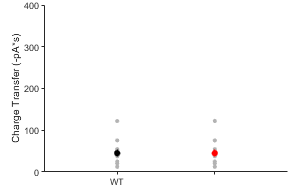

ylim([0 400]);
yticks(0:100:400);


compare2C(rinstatBlock,KOrinstatBlock,conditions,'Input Resistance (MOhm)',[3 2]);

     1



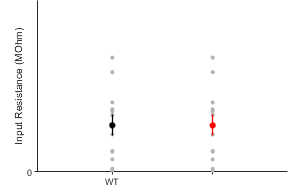

ylim([0 75]);
yticks(0:100:400);


compare2C(vmstatBlock,KOvmstatBlock,conditions,'Vm',[3 2]);

     1



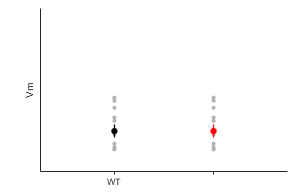

ylim([-100 -75]);
yticks(0:100:400);

% [p,~,stats] = anova1(pkstatBlock);
% [c] = multcompare(stats,'display','off')
% 
% [p,~,stats] = anova1(ampstatBlock);
% [c1] = multcompare(stats,'display','off')
% 
% [p,~,stats] = anova1(intstatBlock);
% [c2] = multcompare(stats,'display','off')